# Dumbbell Laplacian program

Computes the eigenvalues and eigenfunctions of the Laplace operator on a dumbbell graph.

## Set up the graph structure and coordinates of the problem

Use the template function to define the dumbbell quantum graph.

Phi = dumbbell;
Phi.plot('layout')

The layout function is defined by the program `dumbbellPlotCoords` in the `templates` folder. 

## Construct the Laplacian and calculate its eigenvalues and eigenvectors

A little cleanup needed because the null eigenvalue is sometimes calculated as positive and sometimes as negative and this screws up the sorting.

[V,lambda]=eig(Phi);
[singles,doubles,~]=separateEigs(lambda); % No triple eigenvalue unless handle and hoops resonant
nToPlot=4;

## Plot the first few multiplicity-one eigenfunctions

for k=1:nToPlot
    figure
    Phi.plot(V(:,singles(k)))
    title(sprintf('(%s) $\\lambda = %0.3f$', letter(k),lambda(singles(k))));
end

## Plot the first few multiplicity-two eigenfunctions

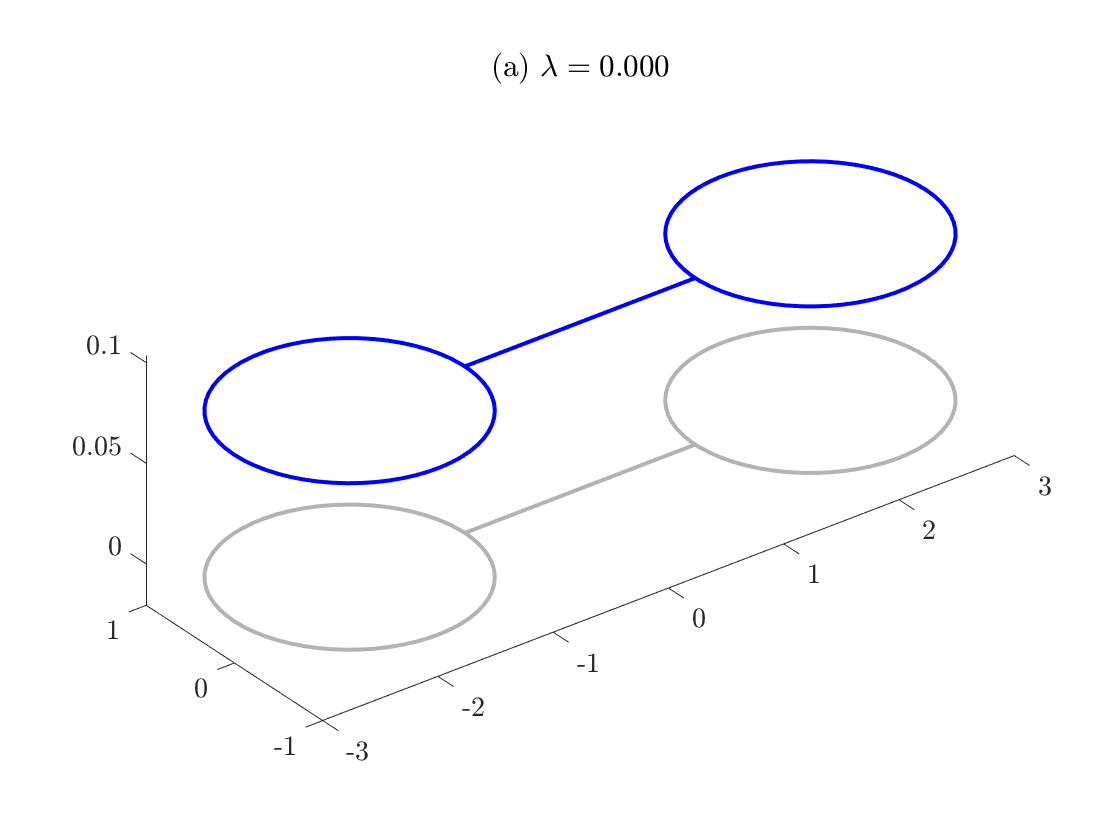

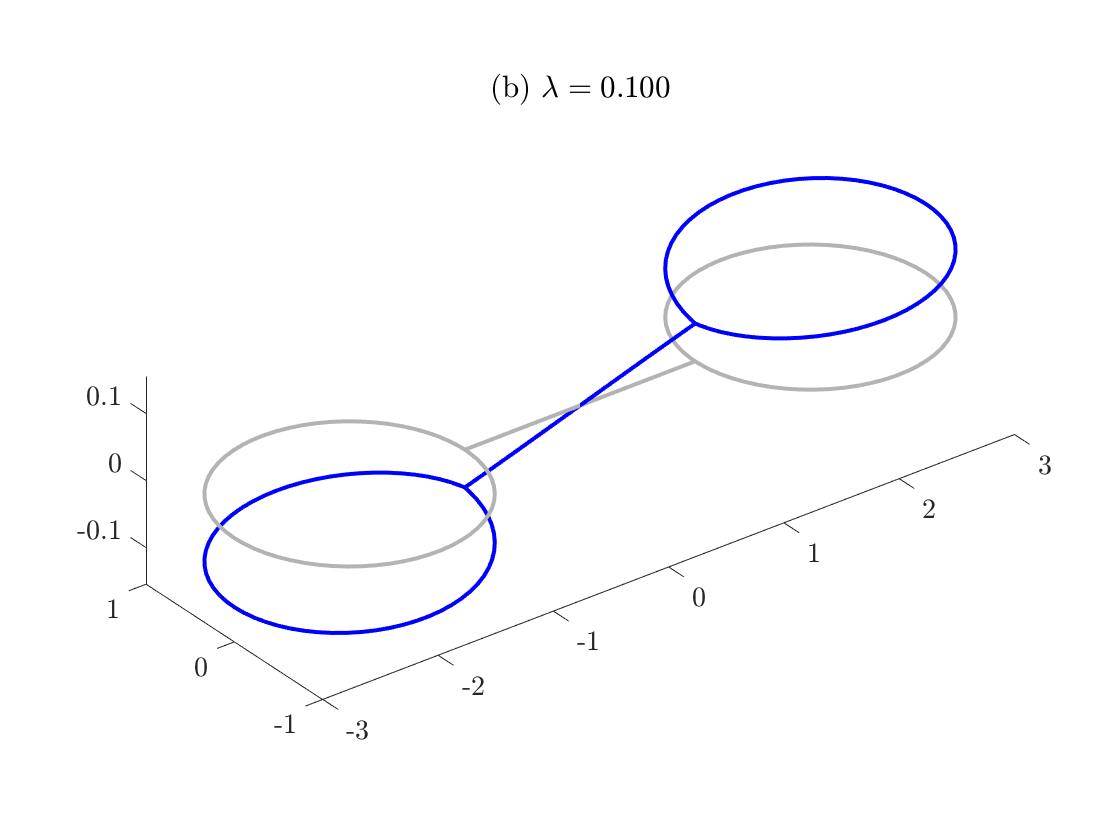

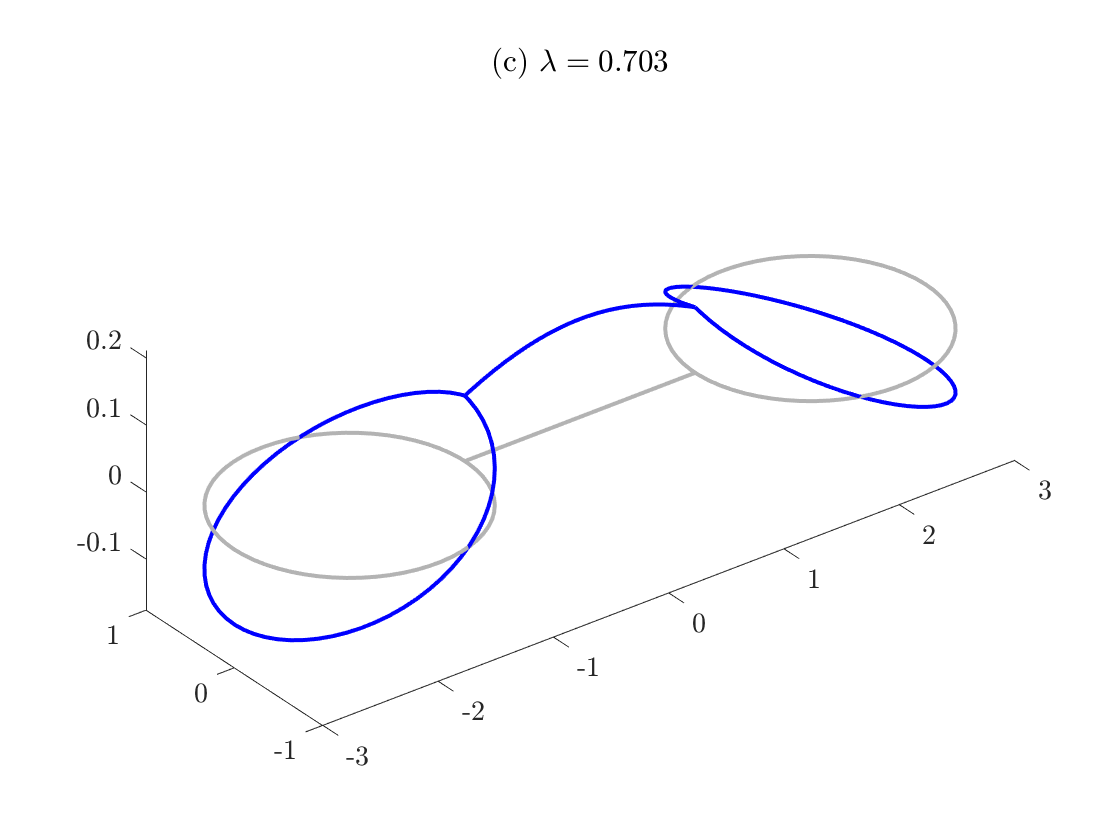

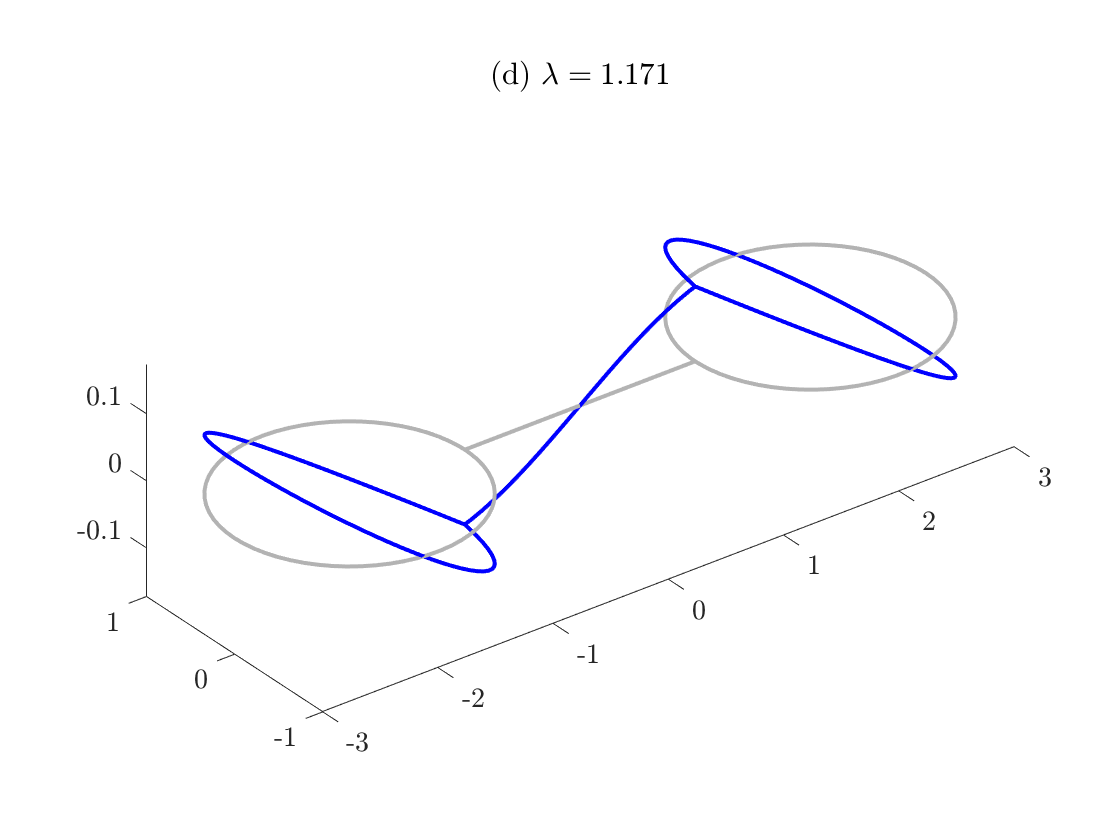

for k=1:nToPlot/2
    figure
    v=dumbbellResolveDoubles(V,doubles(k));
    Phi.plot(v{1})
    title(sprintf('(%s) $\\lambda = %0.3f$', letter(nToPlot+k), lambda(doubles(k))));

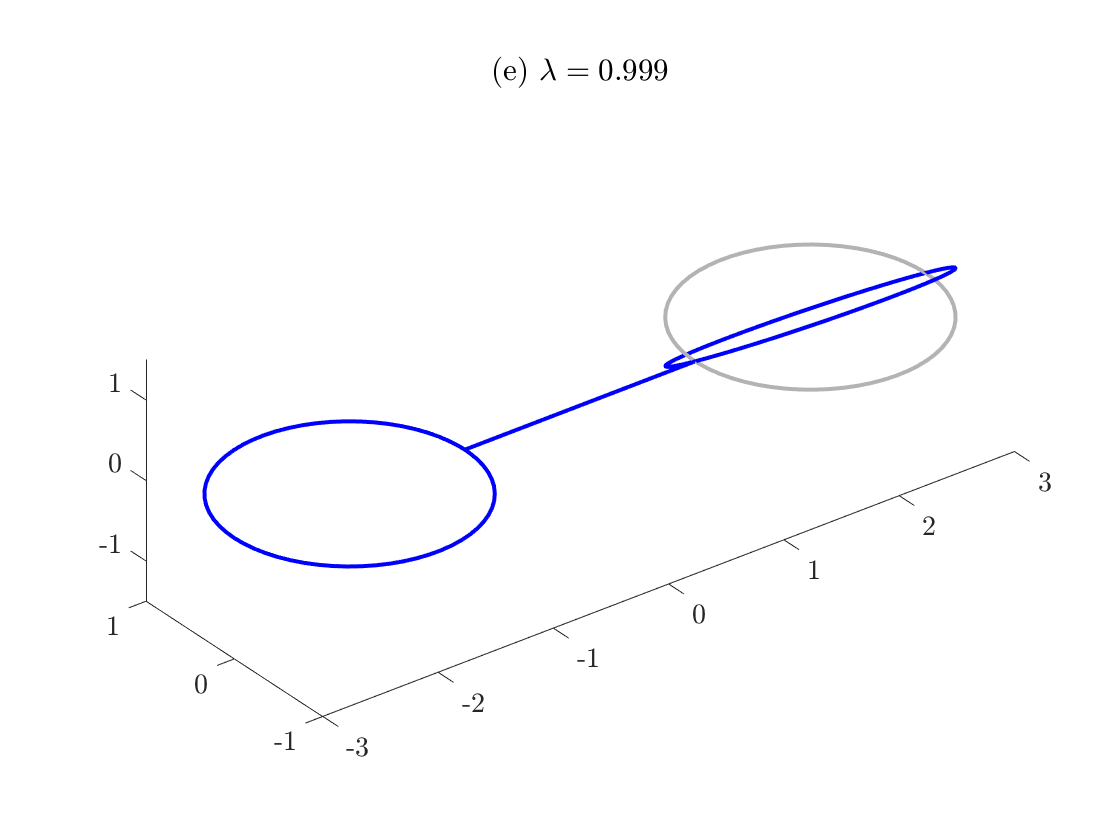

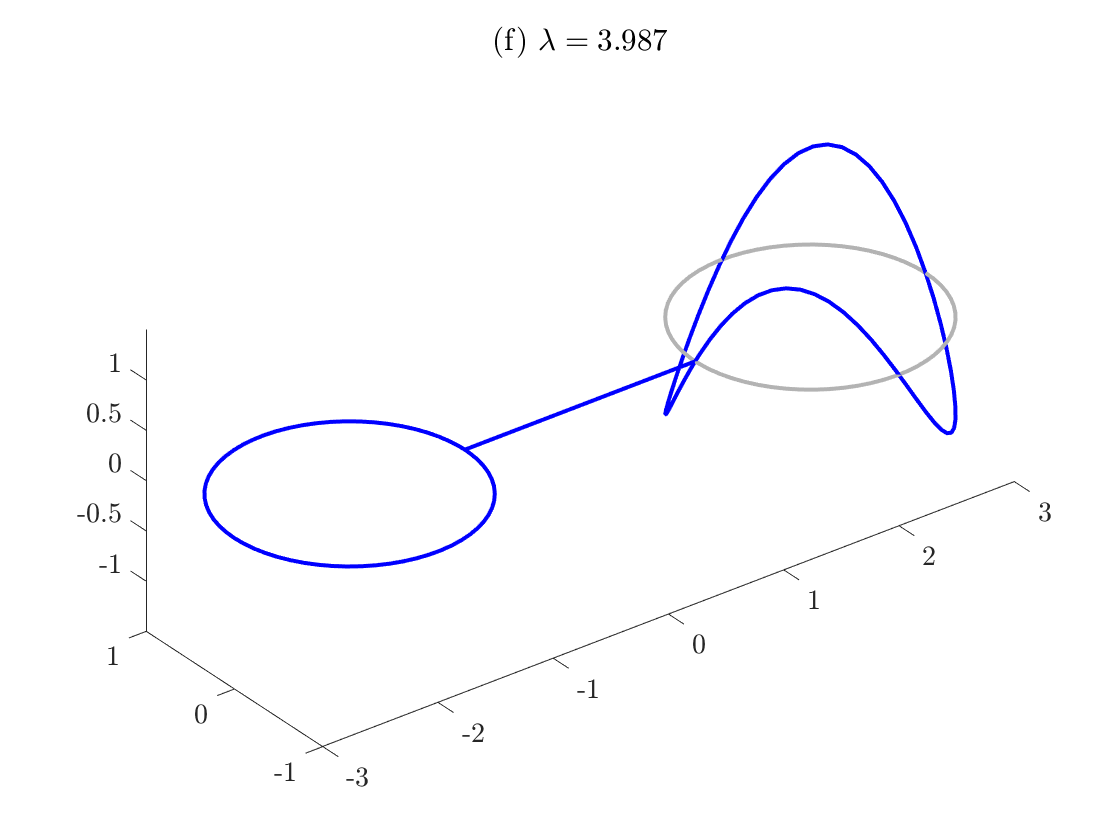

end